# Aero 481 Design01 Walkthrough — constraint diagram, sizing, and T–S

This live script sizes the Aero 481 Design01 fighter from end to end. It builds the Level-1 discipline models, draws the constraint diagram, sizes the aircraft at its real engine and design wing, and then draws the T–S diagram.

This aircraft is a **student design** from the University of Michigan AEROSP 481 course (Design01). It is loosely based on the F-35, but it is **not** the real jet: its aspect ratio and wing differ from the production aircraft, so its sized weight is not the real F-35A weight. The ground truth for this example is the Aero 481 course result, whose A02 sizing algorithm sizes the aircraft to about 62,400 lbf.

Method reference: the Aero 481 starter code (Design01 spec, A02 sizing, A03 mission, the constraint set) mapped onto the framework's generic constraint analysis, mission analysis, and T–S core (metabook Chapter 4, §4.11–§4.12).

This walkthrough does the following steps:

- it builds the Aero 481 Level-1 discipline stack

- it draws the constraint diagram and reads the bounded design corner

- it sizes the aircraft and reports the highlight numbers

- it draws the T–S diagram

## Make the sizing framework visible

This block adds the framework to the MATLAB path. If you already ran `tests/run_all_tests`, the path is set and this block does nothing.

if isempty(which("aero481_spec_path"))
    try
        here = fileparts(matlab.desktop.editor.getActiveFilename);
    catch
        here = pwd;
    end
    root = here;
    while ~isfolder(fullfile(root, "src")) || ~isfolder(fullfile(root, "examples", "Aero481"))
        parent = fileparts(root);
        if strcmp(parent, root)
            error("Could not find the sizing/ root. Add its src/ and examples/ folders to the path, or run this file from inside air_vehicle_design/sizing.");
        end
        root = parent;
    end
    addpath(genpath(fullfile(root, "src")));
    addpath(genpath(fullfile(root, "examples")));
end

## Build the Aero 481 Level-1 discipline stack

The caller builds the discipline objects and injects them. The weights object takes both geometry and propulsion, because the Aero 481 weight model measures a wing delta against the wing area and an engine delta against the sea-level thrust.

sp   = aero481_spec_path(1);
rp   = aero481_requirements_path();
aero = Aero481AeroL1(sp);
prop = Aero481PropL1(sp);
geom = Aero481GeomL1(sp, rp);
tail = Aero481TailL1();
wts  = Aero481WeightsL1(sp, geom, prop);
miss = MissionAnalysisL1.from_requirements(aero, prop, geom, rp, "dca");
stack = table( ...
    ["aero"; "prop"; "geom"; "tail"; "wts"; "miss"], ...
    [string(class(aero)); string(class(prop)); string(class(geom)); ...
     string(class(tail)); string(class(wts)); string(class(miss))], ...
    ["drag polar, constant clean CD0 = Cfe*S_wet/S_ref = 0.014"; ...
     "single F135, no altitude lapse (matches Aero 481)"; ...
     "statistical wetted area + fuselage length"; ...
     "jet-fighter tail volume coefficients"; ...
     "A02 delta model OEW(W_TO) (fraction + wing + engine)"; ...
     "defensive counter-air (DCA) mission fuel"], ...
    'VariableNames', ["Object", "Class", "Role"])

stack = 6×3 table
    Object           Class                                      Role                           
    ______    ___________________    __________________________________________________________

    "aero"    "Aero481AeroL1"        "drag polar, constant clean CD0 = Cfe*S_wet/S_ref = 0.014"
    "prop"    "Aero481PropL1"        "single F135, no altitude lapse (matches Aero 481)"       
    "geom"    "Aero481GeomL1"        "statistical wetted area + fuselage length"               
    "tail"    "Aero481TailL1"        "jet-fighter tail volume coefficients"                    
    "wts"     "Aero481WeightsL1"     "A02 delta model OEW(W_TO) (fraction + wing + engine)"    
    "miss"    "MissionAnalysisL1"    "defensive counter-air (DCA) mission fuel"                


## The constraint diagram

The constraint analysis reads the thirteen fighter conditions: cruise, dash, two sustained turns, six specific-excess-power points, an instantaneous turn, a ceiling, and a stall/approach wall. A fighter reads the diagram opposite to a transport. The maneuver, excess-power, and dash requirements demand a high thrust-to-weight, so they push the envelope up, and the design region is a high thrust-to-weight corner.

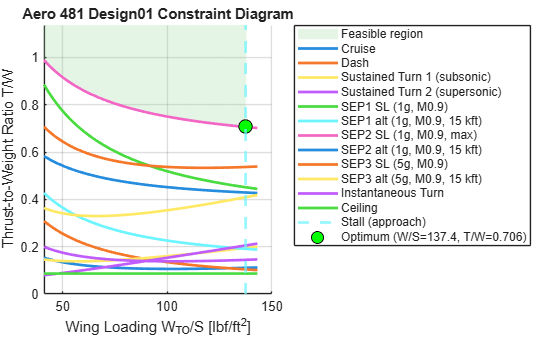

WS_sweep = linspace(41, 143, 200);   % psf (Aero 481 range)
ca = ConstraintAnalysis.from_requirements(aero, prop, rp, ...
    Aero481ConstraintSet.constraint_map(), WS_sweep);
fig = ca.plot_diagram();
fig.Color = 'w';
if isprop(fig, 'Theme'), fig.Theme = 'light'; end
title(fig.CurrentAxes, 'Aero 481 Design01 Constraint Diagram');

The stall/approach wall is the key addition that bounds the design. Aero 481 left its landing case unimplemented, so nothing limited the small-wing side and the least-thrust "optimum" ran to the sweep edge. Adding the wall, at the wing loading where the approach speed reaches the maximum lift, gives a real design corner: the wall meets the binding excess-power floor.

env = ca.envelope();
walls = ca.constraints(cellfun(@(c) isa(c, 'Only_WbyS'), ca.constraints));
WS_wall = min(cellfun(@(c) c.WS_max(), walls));           % stall/approach wall [psf]
TW_wall = interp1(WS_sweep, env, WS_wall, 'linear', NaN);
cornerPoint = table(WS_wall, TW_wall, ...
    'VariableNames', ["WS_wall_psf", "TW_at_wall"], ...
    'RowNames', {'Design corner (wall meets the excess-power floor)'})

cornerPoint = 1×2 table
                                                         WS_wall_psf    TW_at_wall
                                                         ___________    __________

    Design corner (wall meets the excess-power floor)       137.4        0.70613  


## Size the aircraft

Aero 481 sizes the aircraft at a fixed engine and wing, not at the constraint optimum. It uses the real F135 engine, a sea-level thrust of 43,000 lbf, and the design wing of 538 ft². The design thrust-to-weight of 1.2 is aspirational: at the sized weight the actual thrust-to-weight is near 0.70. The A02 weight model credits the difference between the real engine and the aspirational engine as a large negative empty-weight term, which is why the aircraft sizes light.

`converge_W0` is the framework's version of the A02 fixed-cell closure. It writes the thrust and wing area, then iterates the takeoff-weight closure to convergence.

ts = TSDiagram(aero, prop, wts, geom, miss, ca, tail);
T_design = 43000;   % lbf  real F135 sea-level thrust with afterburner
S_design = 538;     % ft^2 Aero 481 design wing (~50 m^2)
W_TO = ts.converge_W0(T_design, S_design);
W_OEW = wts.OEW(W_TO);
[W_fuel, ~] = miss.total_fuel(W_TO);
p     = aero.drag_polar([]);
LDmax = 1 / (2 * sqrt(p.CD0 * p.K1));
tsfc  = prop.get_TSFC(AircraftState(35000, 0.85));
highlights = table( ...
    [W_TO; W_OEW; W_fuel; S_design; W_TO/S_design; T_design/W_TO; LDmax; tsfc], ...
    'VariableNames', "Value", 'RowNames', ...
    {'W_TO  takeoff gross weight [lbf]', 'W_OEW  empty weight [lbf]', ...
     'W_fuel  mission fuel [lbf]', 'S_ref  wing area [ft^2]', ...
     'W/S  wing loading [psf]', 'T/W  actual (43000 / W_TO)', ...
     'L/D_max  (clean polar)', 'cruise TSFC [1/hr]'})

highlights = 8×1 table
                                         Value 
                                        _______

    W_TO  takeoff gross weight [lbf]      61121
    W_OEW  empty weight [lbf]             22382
    W_fuel  mission fuel [lbf]            20298
    S_ref  wing area [ft^2]                 538
    W/S  wing loading [psf]              113.61
    T/W  actual (43000 / W_TO)          0.70353
    L/D_max  (clean polar)                14.48
    cruise TSFC [1/hr]                     0.65


The sized weight reproduces the Aero 481 A02 result of 62,399 lbf within about 2%. The remaining difference is method fidelity, not a bug. The published F-35A is heavier still, because this student Design01 differs from the production jet.

sizedVsA02 = table(W_TO, 62399, 100*(W_TO - 62399)/62399, ...
    'VariableNames', ["Sized", "Aero481_A02", "Percent_diff"])

sizedVsA02 = 1×3 table
    Sized    Aero481_A02    Percent_diff
    _____    ___________    ____________

    61121       62399         -2.0486   


## The T–S diagram

The T–S diagram sweeps the wing area and the thrust, and sizes a complete aircraft at every cell. For this fighter the empty-weight model changes only mildly across the grid, so the fuel field is nearly flat. The substance of the diagram is therefore the constraint curves in the thrust versus wing-area plane, exactly as in the Aero 481 study. No design point is marked, because a single marker on the constraint curves was confusing.

The grid below is coarser than the study script `run_aero481_TS_diagram.m` uses, so the live script stays responsive.

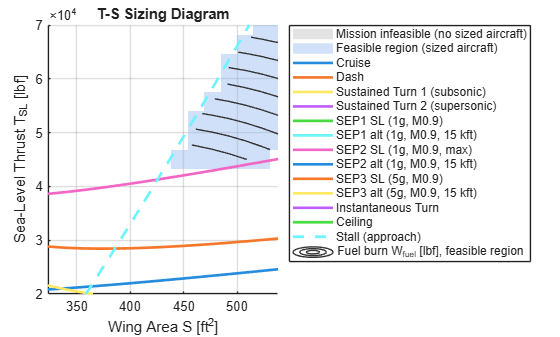

S_grid = linspace(323, 538, 15);      % ft^2 (Aero 481 range, 30-50 m^2)
T_grid = linspace(20000, 70000, 15);  % lbf  (brackets the F135 43,000)
ts.plot('S_grid', S_grid, 'T_grid', T_grid);   % no 'actual' -> no marker

Read the diagram by its curves. Each solid line is one constraint, and the dashed line is the stall/approach wall. The feasible region is bounded on the small-wing side by that wall and above by the excess-power and maneuver constraints, so the design sits at a bounded corner, not at a sweep edge.

## Summary

The Level-1 fighter models placed the thirteen constraints on the diagram, and the stall/approach wall bounded the design corner. The T–S core sized the aircraft at the real engine and design wing, and the weight reproduced the Aero 481 A02 result within about 2%. The T–S diagram showed that the constraint curves, not the fuel field, carry the design for this fighter.

To reproduce these results as stand-alone studies, run `studies/run_aero481_constraint_diagram.m`, `studies/run_aero481_sizing_L1.m`, `studies/run_aero481_TS_diagram.m`, and `sanity_checks/aero481_comparison.m`.